# Rotates EPANET Inp File.

***** For convenience, use EPANET class function appRotateNetwork *** **

This example contains: Load network and paths. Plot nework initial. Rotate degrees theta. Define the x- and y-data for the original line we would like to rotate. Create a matrix of these points, which will be useful in future calculations. Choose a point which will be the center of rotation. Create a matrix which will be used later in calculations. Define a 60 degree counter-clockwise rotation matrix. Do the rotation: Shift points in the plane so that the center of rotation is at the origin. Apply the rotation about the origin. Shift again so the origin goes back to the desired center of rotation. Pick out the vectors of rotated x- and y-data. Plot rotated network. Save rotated Inp file.

Clear

clc; close all; clear;

Load network and paths.

start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('Net1.inp'); 

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


Plot nework initial.

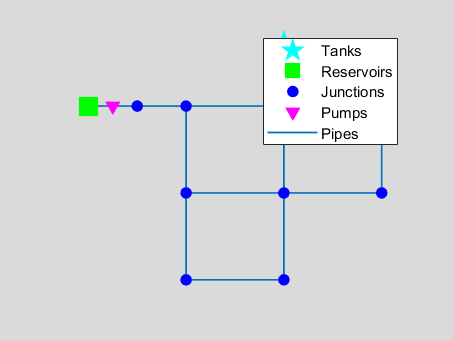

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot

Rotate degrees theta.

theta = pi/3; %60 degrees

Define the x- and y-data for the original line we would like to rotate.

x = d.getNodeCoordinates{1}';
y = d.getNodeCoordinates{2}';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ****
% Create a matrix of these points, which will be useful in future calculations.
v = [x;y];
% Choose a point which will be the center of rotation.
x_center = x(1);
y_center = y(1);
% Create a matrix which will be used later in calculations.
center = repmat([x_center; y_center], 1, length(x));
% Define a 60 degree counter-clockwise rotation matrix.
% theta = pi/3;       % pi/3 radians = 60 degrees
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
% Do the rotation:
v = [v(1:11,1),v(12:22,1)];
s = v - center';     % Shift points in the plane so that the center of rotation is at the origin.
so = R*s';           % Apply the rotation about the origin.
vo = so + center;    % Shift again so the origin goes back to the desired center of rotation.
% this can be done in one line as:
% vo = R*(v - center) + center
% Pick out the vectors of rotated x- and y-data.
x_new = vo(1,:);
y_new = vo(2,:);
% ****
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i=1:d.NodeCount
    d.setNodeCoordinates(i, [x_new(i) y_new(i)]);
end

Plot rotated network.

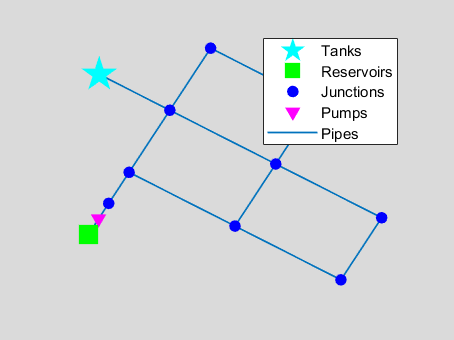

ans =   Axes with properties:

             XLim: [7.8038 94.1577]
             YLim: [42.1962 119.7654]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot

Save rotated Inp file.

d.saveInputFile('rotated.inp');

## Source:

[https://www.mathworks.com/matlabcentral/answers/93554-how-can-i-rotate-a-set-of-points-in-a-plane-by-a-certain-angle-about-an-arbitrary-point](https://www.mathworks.com/matlabcentral/answers/93554-how-can-i-rotate-a-set-of-points-in-a-plane-by-a-certain-angle-about-an-arbitrary-point)